# Study case: Clamped-free beam

The present example is similar to the one used in [5], where the dynamic response of a 100 m high clamped-free steel beam was studied. Simulated time series are used, where the first 4 eigen-modes have been taken into account. These time series correspond to acceleration response of the beam to white noise excitation. The simulated data are generated with the central difference method [1], and the eigen-modes/eigen-frequencies are generated using [2]. A modal damping ratio of 0.005 for every mode is used. These parameters are considered as the "target modal parameters". 

The TDD is an output only modal analysis method inspired from [3] to retrieve the mode shapes and the modal damping ratio from acceleration data. Analysing ambient vibrations data is more challenging than impulse response data due to the lower signal to noise ratio recorded. However, ambient vibrations monitoring is more common for large civil engineering structures. The most challenging task is the estimation of the modal damping ratios (higher sensitivity to measurement noise) which is done for each mode using [4].

## References

[1] https://se.mathworks.com/matlabcentral/fileexchange/53854-harmonic-excitation-of-a-sdof

[2] https://se.mathworks.com/matlabcentral/fileexchange/52075-eigen-value-calculation-of-a-continuous-beam-transverse-vibrations

[3] Byeong Hwa Kim, Norris Stubbs, Taehyo Park,A new method to extract modal parameters using output-only responses, Journal of Sound and Vibration, Volume 282, Issues 1–2, 6 April 2005, Pages 215-230, ISSN 0022-460X, http://dx.doi.org/10.1016/j.jsv.2004.02.026.

[4] https://se.mathworks.com/matlabcentral/fileexchange/55557-modal-parameters-identification-from-ambient-vibrations--sdof

[5] https://se.mathworks.com/matlabcentral/fileexchange/57153-automated-frequency-domain-decomposition--afdd

## Preprocessing

clearvars;close all;clc;
load('beamData.mat')
whos

  Name       Size                 Bytes  Class     Attributes

  Az        30x17238            4137120  double              
  phi        4x30                   960  double              
  t          1x17238             137904  double              
  wn         1x4                     32  double              
  zeta       1x4                     32  double              



fn = wn/(2*pi);
fnMin = [0.1 0.9 2.5 5.5]; % Lower limit for the band-pass filter for each eigenfrequency
fnMax =[0.20,1.1,3.1,6.0]; % Upper limit for the band-pass filter for each eigenfrequency
Nmodes = numel(fn);
fs = 1/median(diff(t));
rng(1)
[Nyy,N]=size(Az); 

## Time series and power spectral density visualization 

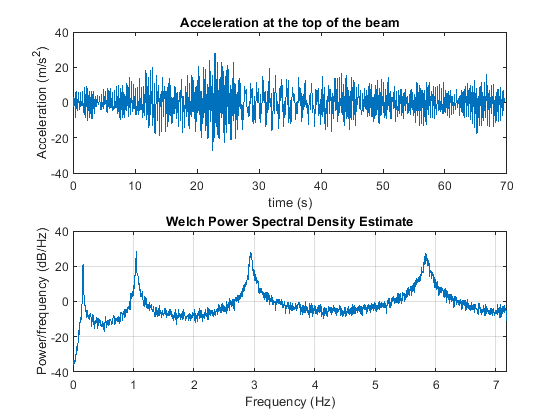

figure
subplot(211)
plot(t(1:1e3),Az(30,1:1e3));
xlabel('time (s)')
ylabel('Acceleration (m/s^2)')
title('Acceleration at the top of the beam')

subplot(212)
pwelch(Az(end,:),[],[],[],1/median(diff(t)))

## Minimalist example

tic
[phi_TDD,zeta,eta] = TDD(Az,fs,fn,fnMin,fnMax);
toc

Elapsed time is 1.332663 seconds.


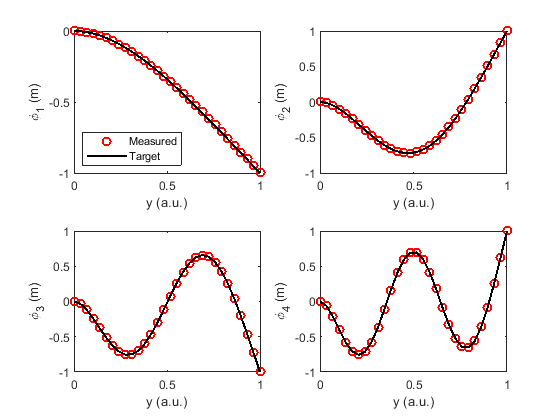


figure
for ii=1:size(phi_TDD),
    subplot(2,2,ii)
    hold on;box on;
    h1 = plot(linspace(0,1,size(phi_TDD,2)),phi_TDD(ii,:),'ro','linewidth',1.5);
    h2 = plot(linspace(0,1,size(phi,2)),-phi(ii,:),'k-','linewidth',1.5);
    xlabel('y (a.u.)')
    ylabel(['\phi_',num2str(ii),' (m)'])
    if ii==1,        legend('Measured','Target','location','SouthWest');    end
end


disp('left: target damping. Right: Estimated damping')

left: target damping. Right: Estimated damping


disp([5e-3*ones(Nmodes,1),zeta(:),])

    0.0050    0.0057
    0.0050    0.0036
    0.0050    0.0053
    0.0050    0.0040



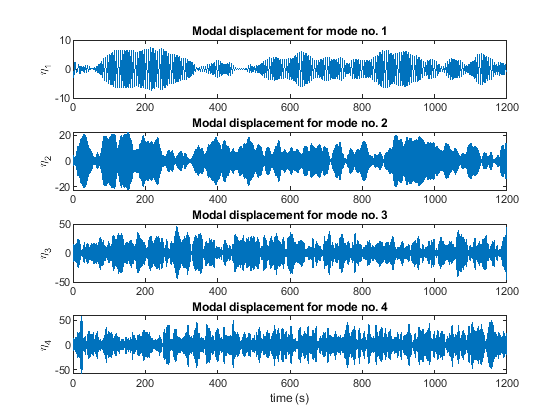



% Display the modal displacements
Nmodes = numel(fn);
figure
for ii=1:Nmodes
    subplot(Nmodes,1,ii)
    plot(t,eta(ii,:))
    ylabel(['\eta_',num2str(ii)])
    title(['Modal displacement for mode no. ',num2str(ii)])
    if ii==Nmodes
        xlabel('time (s)')
    end
end

## Example with options

We specifiy a longer time for the autocorrelation funciton (Ts =40 seconds), This only affects the modal damping ratio.

[phi_TDD,zeta] = TDD(Az,fs,fn,fnMin,fnMax,'Ts',40);
disp('left: target damping. Right: Measured damping')

left: target damping. Right: Measured damping


disp([5e-3*ones(Nmodes,1),zeta(:),])

    0.0050    0.0049
    0.0050    0.0033
    0.0050    0.0052
    0.0050    0.0039



##  Comparison with FDD

The FDD example in [5] more time consuming because the matrix of cross spectral densities must be computed, and the SVD applied at every frequency step. In a previous version,the FDD was included inside this example.To optimize the clarity, the code related to the FDD has been moved in a different submission [5]. The acceleration data in the FDD [5] and the TDD are the same to  facilitate the comparison between the two methods.